open_system("Articulated_arm_real_proportions");



test

path_simu = 'Articulated_arm_real_proportions';

set_param(path_simu, 'SolverType', 'Fixed-step');   % fixed-step solver
%before : set_param(path_simu, 'FixedStep', '0.001');         % time step in sec
set_param(path_simu, 'FixedStep', '0.001'); 
%before set_param(path_simu, 'StopTime', '100'); 
set_param(path_simu, 'StopTime', '100');             % simulate time


Sweep Value

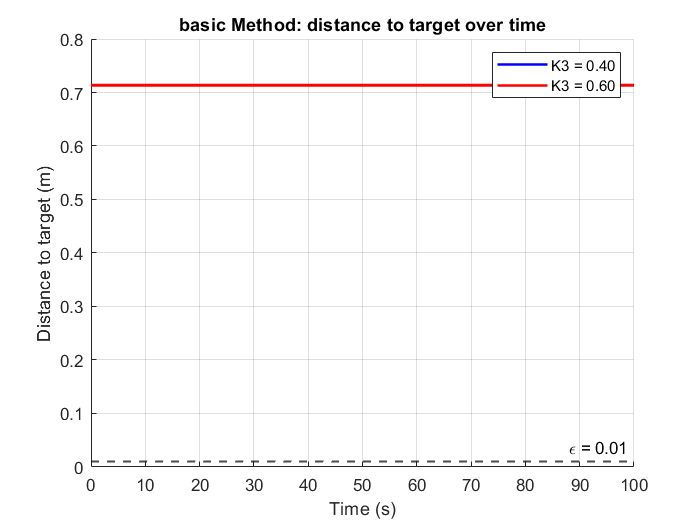

% For the graph
epsilon = 0.01;
method_name = 'basic Method';
figure; hold on; grid on;
colors = {'b','r'};

K1 = 0.08;
K2 = 0.4;
K3vals = [0.4, 0.6];
delta_theta = 0.5;

L1 = 0.145;
L2 = 0.2359;
L3 = 0.4191;
small_seg = -0.0275;

x_target = -0.2;
y_target = 0.5;

f_min = [2 2 2];
f_max = [20 20 20];
frac  = [0.8 0.8 0.8];

nbins = 10;
frac_thresh = 0.7;

counter = 0;


for i3 = 1:numel(K3vals)

    set_param([path_simu '/Gain3'],  'Gain', num2str(K1));
    set_param([path_simu '/Gain9'],  'Gain', num2str(K1));
    set_param([path_simu '/Gain4'],  'Gain', num2str(K2));
    set_param([path_simu '/Gain10'], 'Gain', num2str(K2));
    set_param([path_simu '/Gain5'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/Gain8'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/delta_angle_deg_const'], 'Value', num2str(delta_theta));

    simOut = sim(path_simu);
    logsout = simOut.logsout;

    t = logsout.getElement('theta_1').Values.Time;

    theta_1_signal = logsout.getElement('theta_1');
    theta_2_signal = logsout.getElement('theta_2');
    theta_3_signal = logsout.getElement('theta_3');

    theta_1_array_prev = squeeze(theta_1_signal.Values.Data);
    theta_2_array_prev = squeeze(theta_2_signal.Values.Data);
    theta_3_array_prev = squeeze(theta_3_signal.Values.Data);

    theta_1_array = theta_1_array_prev(:,1);
    theta_2_array = theta_2_array_prev(:,1);
    theta_3_array = theta_3_array_prev(:,1);

    x = L1*cos(theta_1_array+pi/2) + L2*cos(theta_1_array+theta_2_array+pi/2) + L3*cos(theta_1_array+theta_2_array+theta_3_array+pi/2) + small_seg;
    y = L1*sin(theta_1_array+pi/2) + L2*sin(theta_1_array+theta_2_array+pi/2) + L3*sin(theta_1_array+theta_2_array+theta_3_array+pi/2);

    dist = sqrt((x - x_target).^2 + (y - y_target).^2);

    plot(t, dist, colors{i3}, 'LineWidth', 1.5, 'DisplayName', sprintf('K3 = %.2f', K3vals(i3)));

end

yline(epsilon, 'k--', '\epsilon = 0.01', 'LineWidth', 1.2, ...
    'HandleVisibility','off');

xlabel('Time (s)');
ylabel('Distance to target (m)');
title([method_name ': distance to target over time']);
legend('Location','northeast');